# RoadRunner - Simulinkのcosimulationによるパス・車速追従（Vehcile Dynamics Blocksetの14自由度モデルを活用）

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動する

rrApp = roadrunner();

% 必要なシナリオファイル, behaviorファイルをコピー
rrProjectPath = rrApp.status.Project.Filename;
copyfile("pathFollowingUtil/TrajectoryFollowBehavior14DoF.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscene", fullfile(rrProjectPath, "Scenes/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscenario", fullfile(rrProjectPath, "Scenarios/"));

behaviorName = "TrajectoryFollowBehavior14DoF.rrbehavior";
% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("slopeTest14DoF");
rrApp.setScenarioVariable("EgoVehicleBehavior", "<PROJECT>/Assets/Behaviors/" + behaviorName); %behaviorファイルを設定

rrSim = rrApp.createSimulation();
rrSim.set("PacerStatus", "Off");
rrSim.set("MaxSimulationTime", 14);
set(rrSim,"Logging","on");

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));

addpath("pathFollowingUtil");
helperSLTrajectoryFollowerWithRRScenarioSetup(); %車両ダイナミクスパラメータや制御パラメータを設定
% % Simulinkのモデルを開く
model_name = 'TrajectoryFollowVehicleWith14DoF.slx';
open_system(model_name);


% RoadRunnerとSimulinkの実行ステップサイズを揃える
timeStep = 0.01;
RRtimeStep = 0.1;
rrSim.set("StepSize", RRtimeStep);

## シナリオ軌跡通りに車両を動かす

useDynamicsStanley = false; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);
% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end


% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time1 = [velocityAgent1.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor1 = rrLog.get('Pose','ActorID',1);
positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);

rotationActor1_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor1, 'UniformOutput', false))';
rotationActor1_pitch = rad2deg(rotationActor1_eulZYX(:, 3));

## 車両ダイナミクスとして2輪モデル、制御をStanleyControlで実施

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);
% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent2 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time2 = [velocityAgent2.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor2 = rrLog.get('Pose','ActorID',1);
positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);

rotationActor2_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor2, 'UniformOutput', false))';
rotationActor2_pitch = rad2deg(rotationActor2_eulZYX(:, 3));

## 車両ダイナミクスとしてフルビークルモデル(14DoF)、制御をStanleyControlで実施

実行、buildが失敗する方は最後のセクション「実行・ビルドエラーになる方へ」をご覧ください。

## 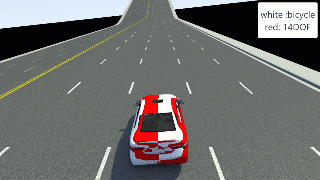

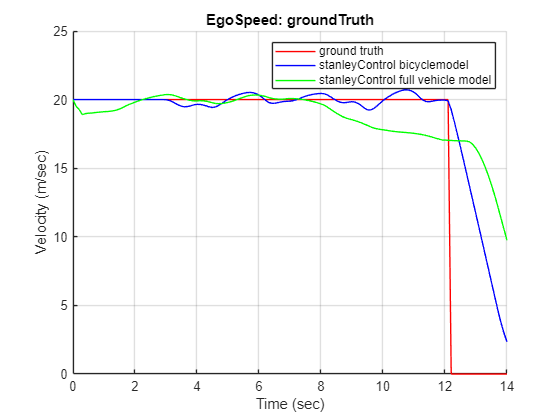

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "14DOF";

% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);

% 事前に作成した地形マップをロード
load("gridMap_groundHeight_RT.mat");
hegihtMap = "2DMap"; %事前に用意した地形マップを使用するモード
debug_engine3D = false;%trueにするとUnreal Engineによる追加表示あり

% Unreal EngineシーンをEmptyに設定
load_system(model_name(1:end-4));
Sim3DConfigPath = model_name(1:end-4)+"/Variant Subsystem/StanleyControl_vehicleDynamics/Vehicle Dynamics1/Vehicle Dynamics 14DOF/3DVisualization/3D Engine/Simulation3DTerrain";
set_param(Sim3DConfigPath, "SourceFile", "");

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time3 = [velocityAgent3.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

rotationActor3_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor3, 'UniformOutput', false))';
rotationActor3_pitch = rad2deg(rotationActor3_eulZYX(:, 3));

## 比較プロット

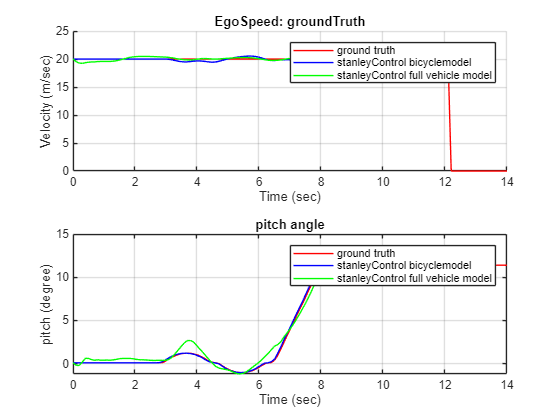

figure; tiledlayout(2, 1); nexttile;
helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3);
title("EgoSpeed: groundTruth");
% 車速減少の関連として、車両ピッチ（路面勾配）を可視化
nexttile;
plot(time1, rotationActor1_pitch, "r"); hold on;
plot(time2, rotationActor2_pitch, "b");
plot(time3, rotationActor3_pitch, "g");
grid on;
ylabel("pitch (degree)")
xlabel("Time (sec)")
legend("ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model")
title("pitch angle");

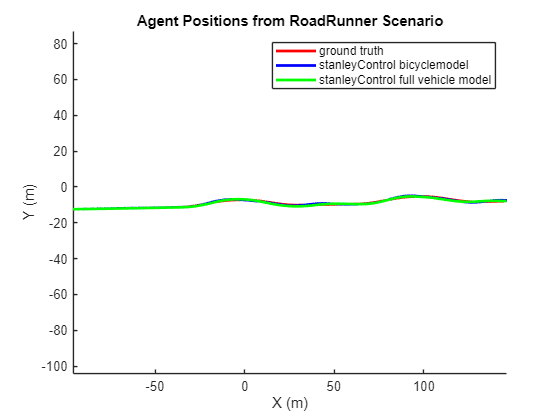


helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y,...
    positionActor3_x, positionActor3_y);

## 「実行・ビルドエラーになる方へ」

想定されるエラーと解決方法は下記になります。

・**エラー1：ビルドが長すぎてRoadRunner ScenarioとSimulinkがタイムアウトになる**

RoadRunnerとSimulinkがcosimulationする際、1ステップの実行時間が長いとTimeoutします。最初の1ステップは車両モデルのビルド時間がかかりますので、Timeoutする可能性があります。

Timeoutの設定を`SimulationConfiguration.xml`で長くすることが可能です。ビルド時間以上の値に設定後、MATLABとRoadRunnerを再起動してください。

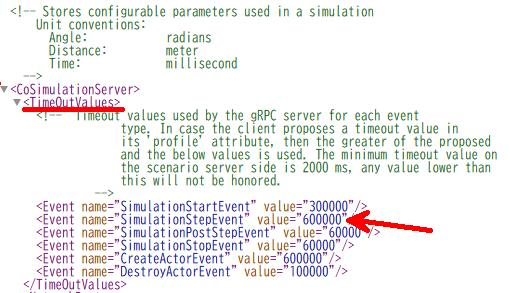

`SimulationConfiguration.xmlは各OSにおいて下記の場所で参照可能です。`

- Windows: `C:\Users\``username``\AppData\Roaming\MathWorks\RoadRunner\``R20NNa``\Scenario\Config\SimulationConfiguration.xml`

- `Ubuntu: ` `~/.local/share/MathWorks/RoadRunner/``R20NNa``/Scenario/Config/SimulationConfiguration.xml`

・エラー2：使用しているコンパイラ設定でビルドエラーになる。

実行時間の短縮のため、車両モデルをAcceleratorに設定し、ビルドしています。ビルドに失敗する場合、下記のようにSimulation modeをNormalに変更してお試しください。

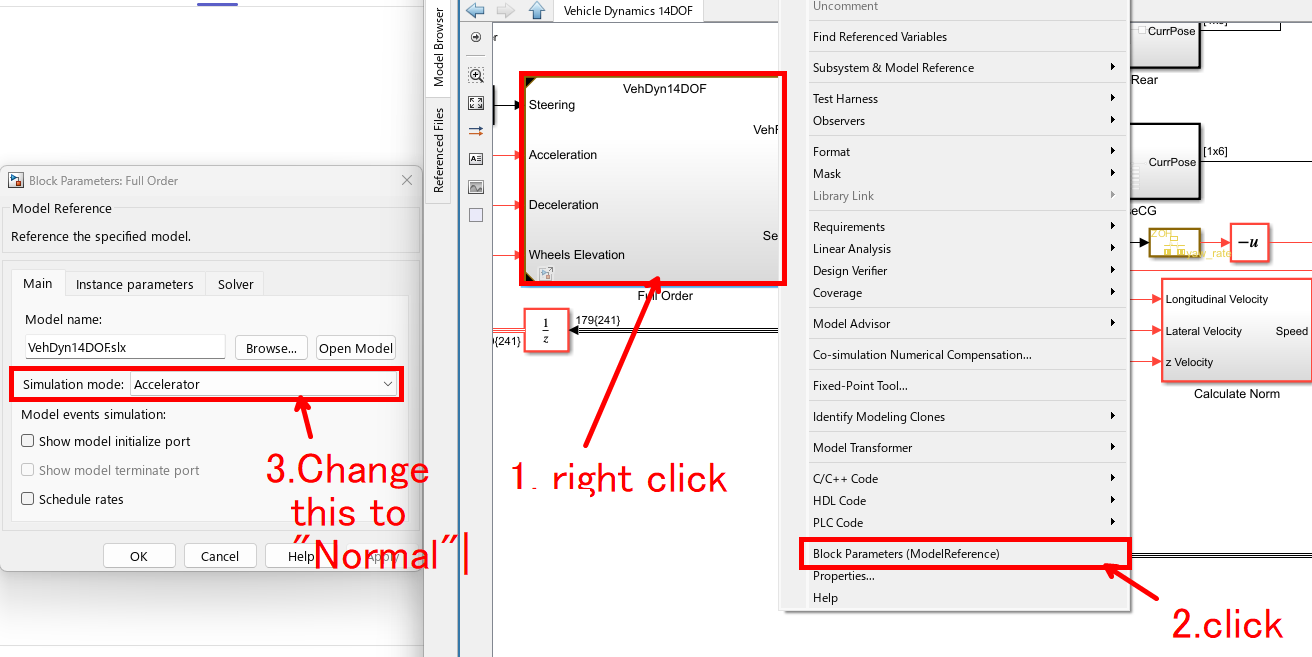

## Helper関数

function helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);
    velMagAgent3 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent3);


    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    hold on
    plot(time1,velMagAgent1,"r")
    plot(time2,velMagAgent2,"b")
    plot(time3,velMagAgent3,"g")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model")
end
function helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y)
    % hdMap = getMap(rrSim);
    % lanes = hdMap.map.lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    % for i = 1:numel(lanes)
    %     control_points = lanes(i).geometry.values;
    %     x_coordinates = arrayfun(@(cp) cp.x,control_points);
    %     y_coordinates = arrayfun(@(cp) cp.y,control_points);
    %     plot(x_coordinates, y_coordinates, 'black');
    % end
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2);
    hold on; axis equal;
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2);
    plot(positionActor3_x,positionActor3_y,"g","LineWidth",2);
    legend("ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model")
    title("Agent Positions from RoadRunner Scenario");
    ylabel("Y (m)");
    xlabel("X (m)");
end